clear; clc;
format long;
apache = csvread('measurementApache.csv', 1, 0);
jama = csvread('measurementJama.csv', 1, 0);
matlab = csvread('measurementMatlab.csv', 1, 0);
matlabGPU = csvread('measurementMatlabGPU.csv', 1, 0);

ls_apache = LeastSquare;
ls_apache.A = apache(:,1);
ls_apache.b = apache(:,2);
resultVector_apache = ls_apache.solveLeastSquare(3);

start least square
Elapsed time is 0.000059 seconds.
Elapsed time is 0.000245 seconds.


flipVector_apache = flipud(resultVector_apache);
polynom_apache = poly2sym(flipVector_apache);

ls_jama = LeastSquare;
ls_jama.A = jama(:,1);
ls_jama.b = jama(:,2);
resultVector_jama = ls_jama.solveLeastSquare(3);

start least square
Elapsed time is 0.000046 seconds.
Elapsed time is 0.000211 seconds.


flipVector_jama = flipud(resultVector_jama);
polynom_jama = poly2sym(flipVector_jama);

ls_matlab = LeastSquare;
ls_matlab.A = matlab(:,1);
ls_matlab.b = matlab(:,2);
resultVector_matlab = ls_matlab.solveLeastSquare(3);

start least square
Elapsed time is 0.000045 seconds.
Elapsed time is 0.000211 seconds.


flipVector_matlab = flipud(resultVector_matlab);
polynom_matlab = poly2sym(flipVector_matlab);

ls_matlabGPU = LeastSquare;
ls_matlabGPU.A = matlabGPU(:,1);
ls_matlabGPU.b = matlabGPU(:,2);
resultVector_matlabGPU = ls_matlabGPU.solveLeastSquare(3);

start least square
Elapsed time is 0.000046 seconds.
Elapsed time is 0.000209 seconds.


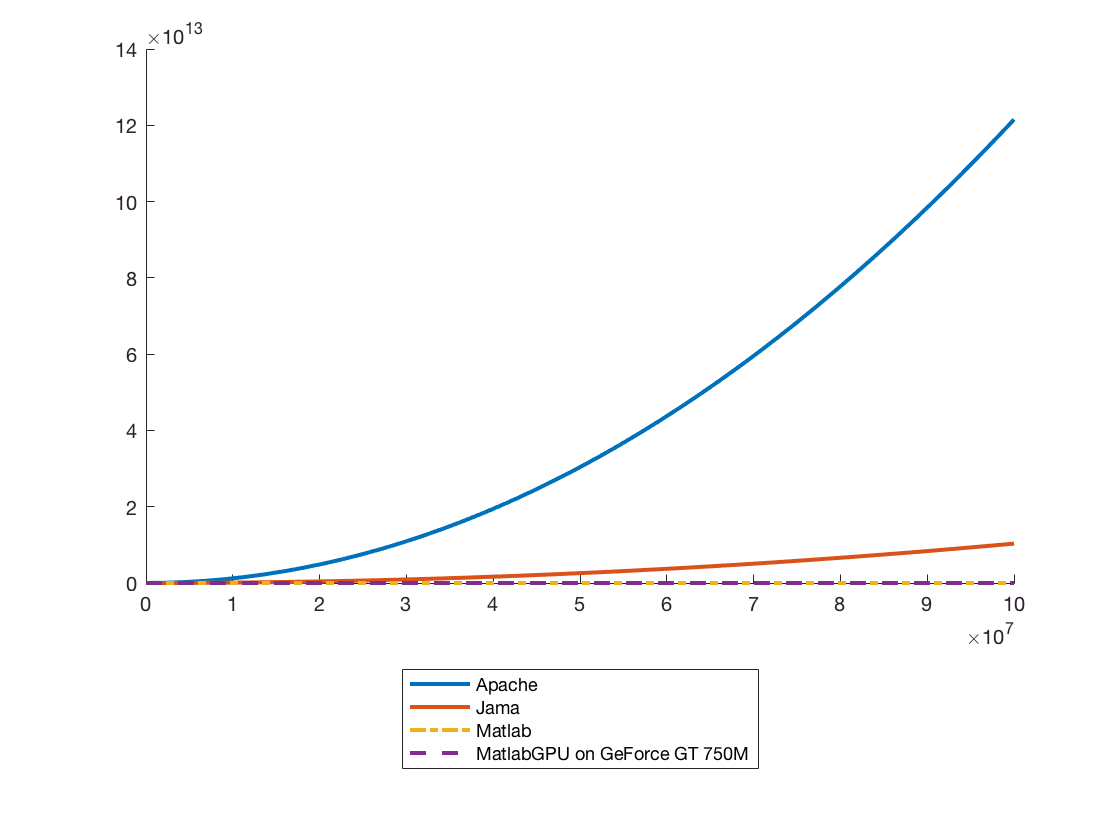

flipVector_matlabGPU = flipud(resultVector_matlabGPU);
polynom_matlabGPU = poly2sym(flipVector_matlabGPU);

hold on;
plot1 = fplot(polynom_apache, [0, 10E10], 'LineWidth',2); 
label1 = 'Apache';
hold off;

hold on;
plot2 = fplot(polynom_jama, [0, 10E10], 'LineWidth',2); 
label2 = 'Jama';
hold off;

hold on;
plot3 = fplot(polynom_matlab, [0, 10E10], '-.',  'LineWidth',2); 
label3 = 'Matlab';
hold off;

hold on;
plot4 = fplot(polynom_matlabGPU, [0, 10E10], '--', 'LineWidth',2); 
label4 = 'MatlabGPU on GeForce GT 750M';
hold off;

title('Comparison between Apache, Jama libraies and Matlab calculated in Matlab');
legend(label1, label2, label3, label4,'Location','southoutside');